# Demod and Sine Tests

## Clear Workspace

close all; clearvars; clc;

## Initalize Variables

dfhz = -90.0548;
numChannels = 8;

## Load Empty Tank and Compute Epiv

load("./Control_Script/Saved_Data_Files/Empty_Tank.mat");
Epiv = computeEpiv(frq+dfhz, N, sampleRate);
emptyTank = fullDemod(rawElectrodeData,Epiv);

## Load Reconstruction Matrix 

reconstruction = load("./Imaging_Control/reconstruction.mat") ;

MatrixA_int = reconstruction.MatrixA_int;
mask = reconstruction.mask;
n_pixels = reconstruction.n_pixels;

clear reconstruction;

## Load Right Tank

load("./Control_Script/Saved_Data_Files/Object_Bottom_Tank.mat");

Tank = fullDemod(rawElectrodeData,Epiv);

## Generate Image

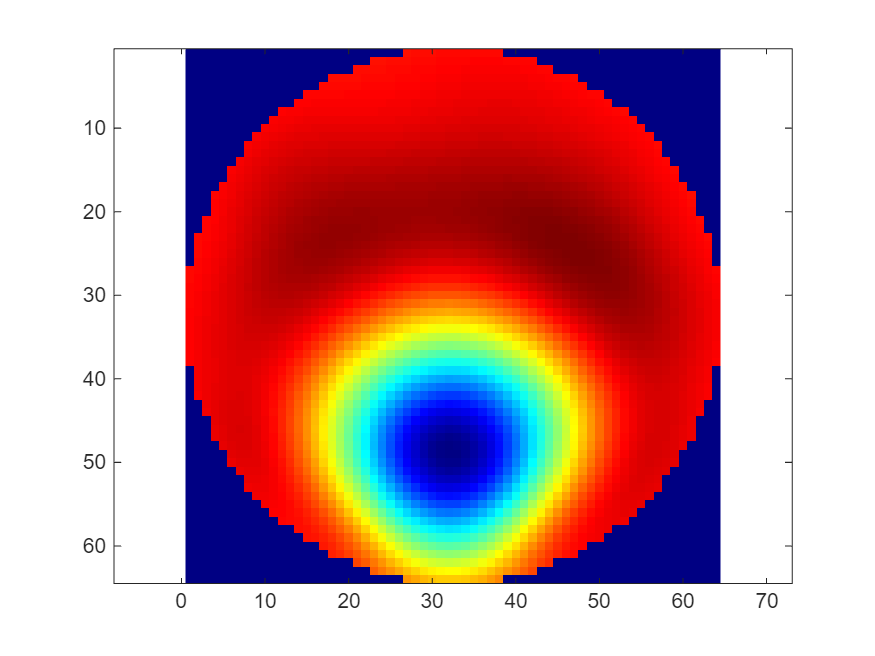

volt_vec_diff = Tank - emptyTank;
imagem = real(MatrixA_int*volt_vec_diff) .* mask ;

figure
imagesc( reshape(imagem', n_pixels , n_pixels) ); 
axis equal ; 
colormap jet ;

## Precompute Epiv Vector

function Epiv = computeEpiv(frq, N, sampleFrq)
    tk = ((0:N-1)/sampleFrq)'; % xAxis
    
    w = 2*pi*frq.*tk;     % frequency converted to anglar frequency (rad/s)
    
    % matrix containing the desired frequency component of the system
    Etot = [sin(w), cos(w)];
    if(size(frq)==1)
        Etot = [Etot, ones(N, 1)];
    else
        for ii = 2:3:(size(Etot,2)*1.5)
            Etot = [Etot(:,1:ii), ones(1, length(tk))', Etot(:,ii+1:end)];
        end
    end

    Epiv = pinv(Etot);
end

## Frequency Demodulation

function realAmp = multiFreqDemod(signal, Epiv, inject) % signal, frq, sampleLen, sampleFreq or signal, Etot
    phi_tot = (Epiv*signal)';
    %phi_tot = reshape(phi_tot, [], 3); % Rearrange to useful order

    amp = sqrt(phi_tot(:,1).^2+phi_tot(:,2).^2);
    phase = atan2(phi_tot(:,2), phi_tot(:,1));
    phase = phase - phase(inject+1);

    realAmp = real(amp.*exp(1i.*phase));

end

## Demod Full Vect

function voltVec = fullDemod(sig, Epiv)
    numChannels = size(sig,2);
    voltVec = zeros(numChannels^2, 1);
    for i = 0:1:numChannels-1
       voltVec(i*numChannels+1:(i+1)*numChannels)  = multiFreqDemod(squeeze(sig(i+1,:,:))', Epiv, i);
    end
end